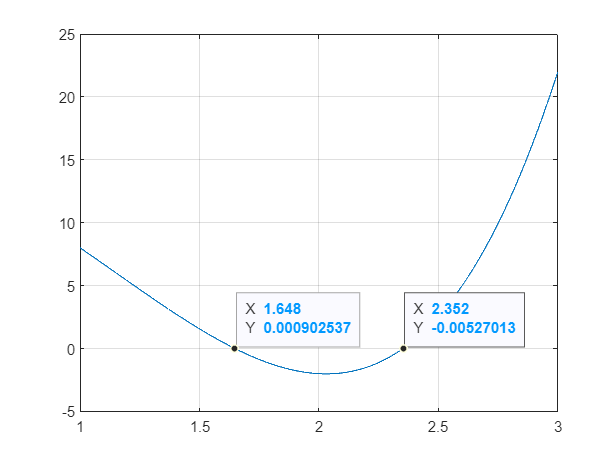

    x_val = 1:0.001:3;
    y_values = (func(x_val));
    
 
    plot(x_val,y_values);


    %genom både grafens plottnig och nedanstående y1 och y2 värden ser man
    %att nollpunkten av funktionen befinner sig mellan y1 och y2 där y1
    %blir 8 vid x = 1 och y2 blir -2 vid x = 2

    y1 = func(1);
    y2 = func(2);
  %% nu ska newton raphsons metod användas
  %%först behövs derivatan av funktionen vilket är 

%% dy/dx = 4x^3 - 16x - 1 denna uttrycks som "funcprim" nedanför 

%%newton raphsons metod som räknar ut den första roten vid ungeför 1.65
tolerance = 0.0001;
x1 = 1.5 ;%%lämpligt startvärde att börja från 
    for i = 2:-0.0001:0.2
        
        a =  func(x1);
        b  = funcprim(x1);
        
        x2 = x1  - a/b;
        diff = func(x2) - func(x1);
        if  abs(diff) <= tolerance
            break;
        end
        x1=x2;
    
    

    end

    %%första punkten 
    ax = gca;
chart = ax.Children(1);
datatip(chart,x2,func(x2));


%%newton raphsons metod som räknar ut den andra roten vid ungeför 2.35
x1 = 2  ;%%lämpligt startvärde att börja från 
    for i = 2:-0.0001:0.2
        
        a =  func(x1);
        b  = funcprim(x1);
        
        x2 = x1  - a/b;
        diff = func(x2) - func(x1);
        if  abs(diff) <= tolerance
            break;
        end
        x1=x2;
    
    

    end

    %andra punkten
    ax = gca;
chart = ax.Children(1);
datatip(chart,x2,func(x2));
    grid on;

    function y = func(x)
        
 y = x.^4 - 8*x.^2 - x +16;   

    end

    function y = funcprim(x)
        
     y = 4*x.^3 - 16*x - 1;

    end

